# Module 3, Lesson 3: Smoothing data

This live script includes the code shown in the "Smoothing Data" video. Try using the Live Editor Tasks below to explore the various methods and options you can use to smooth data.

## Load data

Load the data from June

flights = importFlightsData("flightsJun.csv");

To speed up this analysis, the code below creates a smaller table using data from the first week only.

flightsWeek = flights(flights.SCHEDULED_DEPARTURE_TIME < "2015-06-08 04:00:00",:)

flightsWeek = 115995×20 table
         AIRLINE         TAIL_NUMBER    FLIGHT_NUMBER    ORIGIN    DESTINATION    SCHEDULED_DEPARTURE_TIME    ACTUAL_DEPARTURE_TIME    DEPARTURE_DELAY    TAXI_OUT    AIR_TIME    TAXI_IN    SCHEDULED_ARRIVAL_TIME    ACTUAL_ARRIVAL_TIME     ARRIVAL_DELAY    SCHEDULED_ELAPSED_TIME    ACTUAL_ELAPSED_TIME    DISTANCE    CANCELLED    CANCELLATION_CODE    DIVERTED
    _________________    ___________    _____________    ______    ___________    ________________________    _____________________    ________

## Use `groupsummary` to bin flights by minute

Since there are multiple flights occurring every minute, you can use `groupsummary` to bin the flights data by minute. The result will be a single number for every minute of the day for each month.

First, create a variable called MINUTE_OF_MONTH that has the number of minutes from the 1st of the month.

flightsWeek.MINUTE_OF_MONTH = minutes(flightsWeek.SCHEDULED_DEPARTURE_TIME - "2015-06-01 00:00:00");

Now use this as the grouping variable with `groupsummary` to calculate the mean of `ARRIVAL_DELAY`. This will average together all the flights that are scheduled to depart in the same minute.

resultsWeek = groupsummary(flightsWeek,"MINUTE_OF_MONTH","mean","ARRIVAL_DELAY")

resultsWeek = 7748×3 table
    MINUTE_OF_MONTH    GroupCount    mean_ARRIVAL_DELAY
    _______________    __________    __________________

          10                1                  97      
          15                5                  -4      
          25                3             -5.6667      
          26                1                  -9      
          27                1                  16      
          30               10                  69      
          35                5                34.2      
          37                2                  54      
          40                5                0.25      
          45                4                7.25      
          50                1                  -5      
          55                5                 6.4      
          59                2                  10      
          60                1 

Create a plot to see the noisy signal. Note that this table contains missing values.

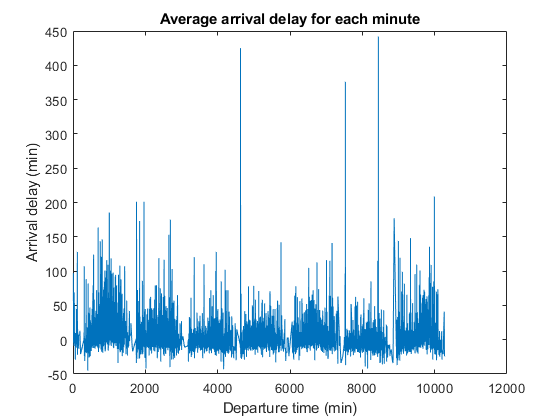

plot(resultsWeek.MINUTE_OF_MONTH,resultsWeek.mean_ARRIVAL_DELAY)
xlabel("Departure time (min)")
ylabel("Arrival delay (min)")
title("Average arrival delay for each minute")

You may notice a trend that repeats around every 1500 minutes. This is a daily trend, since there are 24*60 = 1440 minutes in a day.

However, this trend is difficult to see due to the noise in the signal. 

## Removing missing data

Before you can smooth this data, you need to remove missing rows from the results table. These are minutes that had scheduled flights, but they were cancelled or diverted.

results = rmmissing(resultsWeek,"DataVariables","mean_ARRIVAL_DELAY")

results = 7741×3 table
    MINUTE_OF_MONTH    GroupCount    mean_ARRIVAL_DELAY
    _______________    __________    __________________

          10                1                  97      
          15                5                  -4      
          25                3             -5.6667      
          26                1                  -9      
          27                1                  16      
          30               10                  69      
          35                5                34.2      
          37                2                  54      
          40                5                0.25      
          45                4                7.25      
          50                1                  -5      
          55                5                 6.4      
          59                2                  10      
          60                1     

Notice that you removed less than 100 rows.

## Smooth data task

Now you can begin smoothing. Use the Smooth Data Live Task to smooth the `mean_ARRIVAL_DELAY` column using the `MINUTE_OF_MONTH` column as the x-axis.

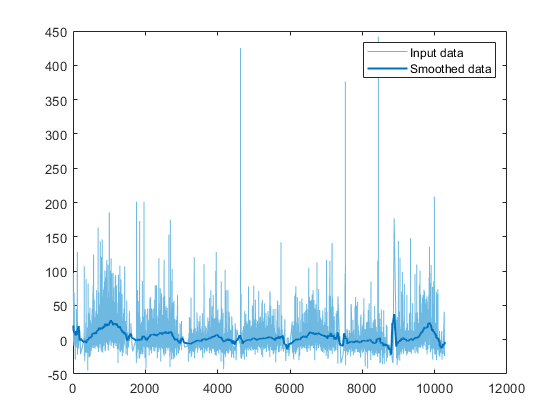

% Smooth input data
smoothedData = smoothdata(resultsWeek.mean_ARRIVAL_DELAY,'movmean',100,...
    'SamplePoints',resultsWeek.MINUTE_OF_MONTH);

% Visualize results
clf
plot(resultsWeek.MINUTE_OF_MONTH,resultsWeek.mean_ARRIVAL_DELAY,...
    'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(resultsWeek.MINUTE_OF_MONTH,smoothedData,'Color',[0 114 189]/255,...
    'LineWidth',1.5,'DisplayName','Smoothed data')
hold off
legend

## Averaging all the days together

To definitively see the daily trend, you can average all the data together before smoothing. Create a `MINUTE_OF_DAY` column using the `timeofday` function.

flights.MINUTE_OF_DAY = minutes(timeofday(flights.SCHEDULED_DEPARTURE_TIME));

Use `groupsummary` again with `MINUTE_OF_DAY` as the grouping variable.

results = groupsummary(flights,"MINUTE_OF_DAY","mean","ARRIVAL_DELAY")

results = 1189×3 table
    MINUTE_OF_DAY    GroupCount    mean_ARRIVAL_DELAY
    _____________    __________    __________________

          3              13              58.462      
          5              66              16.338      
          8              27              24.407      
         10              44              26.651      
         15             137              6.7985      
         19               1                   9      
         21               4                  22      
         22              27              23.615      
         24              23             -4.5455      
         25             105             -2.1333      
         26               4                  -8      
         27              28              6.8889      
         29               2                 -23      
         30             181             -1.2944      
         3

Now look at the arrival delay. The first 300 minutes (before 5 am) have very few flights, so the data is quite sparse and noisy. Butthere's an interesting trend starting at 300 min (5 am) where the delays increase over time, followed by a decrease.

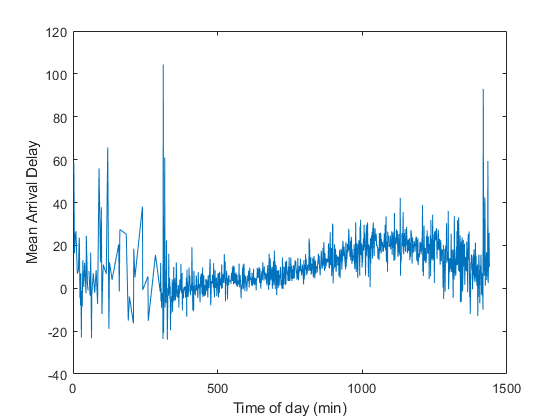

plot(results.MINUTE_OF_DAY,results.mean_ARRIVAL_DELAY)
xlabel("Time of day (min)")
ylabel("Mean Arrival Delay")

## Smooth arrival delay to make the daily trend more apparent

To analyze the main part of the day, you can filter the table where most of the flights occur. Essentially, you're ignoring the noisy section in the early morning when there are very few flights.

results = results(results.MINUTE_OF_DAY>=360 & results.MINUTE_OF_DAY<1320,:);

Now use another Smooth Data task to smooth this data.

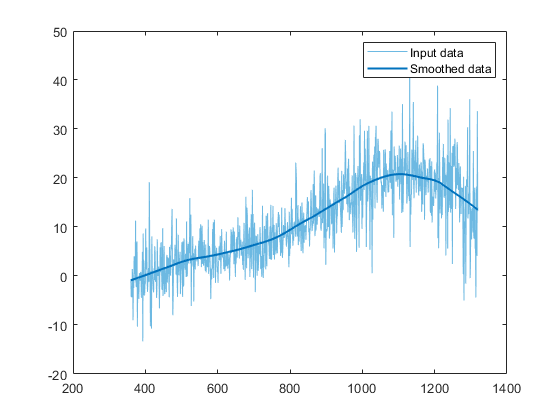

% Smooth input data
smoothedData3 = smoothdata(results.mean_ARRIVAL_DELAY,...
    'lowess','SmoothingFactor',0.4,'SamplePoints',results.MINUTE_OF_DAY);

% Visualize results
clf
plot(results.MINUTE_OF_DAY,results.mean_ARRIVAL_DELAY,...
    'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(results.MINUTE_OF_DAY,smoothedData3,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend

## Generate code from the Live Task

Remember that you can generate code from the Live Task to reproduce this analysis by selecting Controls and Code or Code Only from the top-right of the task.

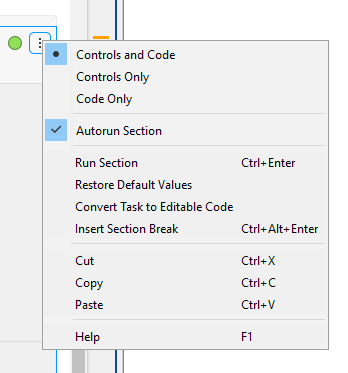

Below is an example of code produced by the task. You can see the `smoothdata` function was used to perform the actual smoothing.

% Smooth input data
smoothedData3 = smoothdata(results.mean_ARRIVAL_DELAY,...
  'lowess','SmoothingFactor',0.4,'SamplePoints',results.MINUTE_OF_DAY);

% Visualize results
clf
plot(results.MINUTE_OF_DAY,results.mean_ARRIVAL_DELAY,...
  'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(results.MINUTE_OF_DAY,smoothedData3,'Color',[0 114 189]/255,'LineWidth',1.5,...
  'DisplayName','Smoothed data')
hold off
legend